close("all"); clear; clc;
setmadsympath;

t = sym('t');
N = Frame;
O = Point;

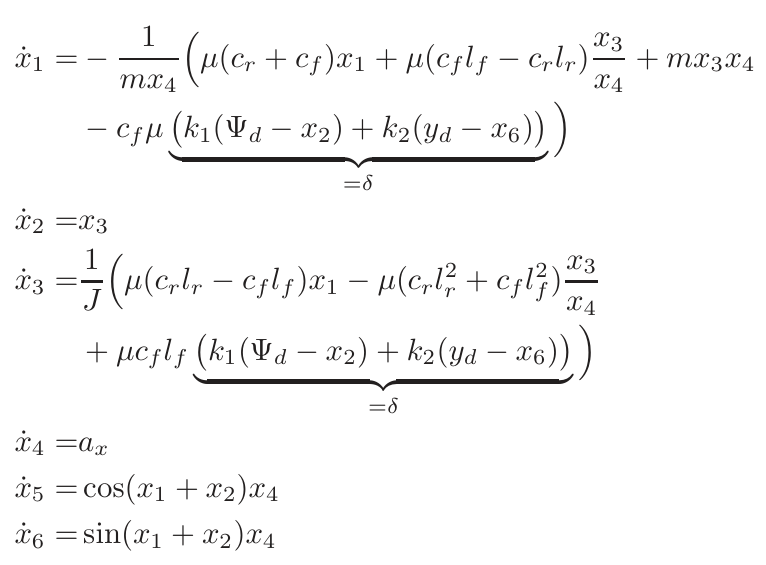

## Body

### Chassis

Orientation :

yaw = DynamicVariable("psi",0,0,0);
Nyaw = orientNew(N,'z',state(yaw));

Position :

lr = sym("l_r");
vx0 = sym("V");

px = DynamicVariable("p_x",0,lr,vx0);
py = DynamicVariable("p_y",0,0,0);
P = locateNew(O,state(px)*N.x + state(py)*N.y);

Body :

m = sym('m');
Izz = sym('I_zz');
B = Body(Nyaw,P,diag([0,0,Izz]),m);

### Front contact point

Orientation :

steer = DynamicVariable("delta",0,0,0);
Ns = orientNew(Nyaw,'z',state(steer));

Position :

lf = sym("l_f");
Cf = locateNew(P,lf*Nyaw.x);

### Rear contact point

lr = sym("l_r");
Cr = locateNew(P,-lr*Nyaw.x);

## Generalized coordinates

q = [
    yaw;
    px;
    py
    ];

## Forces and Moments

b = sym("mu");

### Front tire lateral force

Slip angle :

Vf = vector(Twist(Pose(Ns,Cf)));
slip_f = atan(Vf(5)/Vf(4));

Force :

kf = sym("C_f");
applyForce(B,Nyaw,Cf,b*kf*slip_f*N.y);

### Rear tire lateral force

Slip angle:

Vr = vector(Twist(Pose(Nyaw,Cr)));
slip_r = atan(Vr(5)/Vr(4));

Force :

kr = sym("C_r");
applyForce(B,Nyaw,Cr,b*kr*slip_r*N.y);

### Throttle/braking force

ax = DynamicVariable("a_x",0,0,0);
applyForce(B,Nyaw,P,m*state(ax)*N.x);

## Quasi-velocities

wz = DynamicVariable("omega_z",0,0,0);
vx = DynamicVariable("v_x",0,vx0,0);
vy = DynamicVariable("v_y",0,0,0);

u = [
    wz;
    vx;
    vy
    ];

## Kinematics

V = vector(Twist(Pose(Nyaw,P)));

kdes = [
    state(wz) - V(3);
    state(vx) - V(4);
    state(vy) - V(5)
    ];

## Equations of motion

F = [
    steer;
    ax
    ];

eom = kanesMethod(q,u,kdes,B,F);
eqns = simplify(expand(sym(eom)));

## Substitutions

slip = DynamicVariable("beta",0,0,0);
vy_sub = state(vx)*tan(state(slip));
eqns = subs(eqns,state(vy),vy_sub);

## Dynamical equations

x = [
    slip;
    yaw;
    wz;
    vx;
    px;
    py
    ];

## Linearization

z = [
    x;
    F
    ];

z0 = [z.TrimState].';
dz0 = [z.TrimRate].';

ovars = [
    diff(state(z),t);
    state(z)
    ];

nvars = [
    dz0;
    z0
    ];

dJ = jacobian(eqns,diff(state(z),t));
dJ0 = subs(dJ,ovars,nvars);

J = jacobian(eqns,state(z));
J0 = subs(J,ovars,nvars);

ddz = diff(state(z),t) - dz0;
dz = state(z) - z0;
leqns = dJ0*ddz + J0*dz;

[M,f] = massMatrixForm(leqns,state(x));
M = simplify(expand(M));
f = simplify(expand(f));

odes = collect(simplify(expand(M\f)),state(x));
pprint(odes)

$$\left[\begin{array}{c} \frac{\beta \,\left(C_{f}\,V\,\mu +C_{r}\,V\,\mu \right)}{V^{2}\,m}-\frac{\omega_{z}\,\left(m\,V^{2}-C_{f}\,l_{f}\,\mu +C_{r}\,l_{r}\,\mu \right)}{V^{2}\,m}-\frac{C_{f}\,\delta \,\mu }{V\,m}\\ \omega_{z}\\ \frac{\beta \,\mu \,\left(C_{f}\,V\,l_{f}-C_{r}\,V\,l_{r}\right)}{I_{\mathrm{zz}}\,V}-\frac{C_{f}\,\delta \,l_{f}\,\mu }{I_{\mathrm{zz}}}+\frac{\mu \,\omega_{z}\,\left(C_{f}\,{l_{f}}^{2}+C_{r}\,{l_{r}}^{2}\right)}{I_{\mathrm{zz}}\,V}\\ a_{x}\\ v_{x}\\ V\,\beta +V\,\psi \end{array}\right]$$